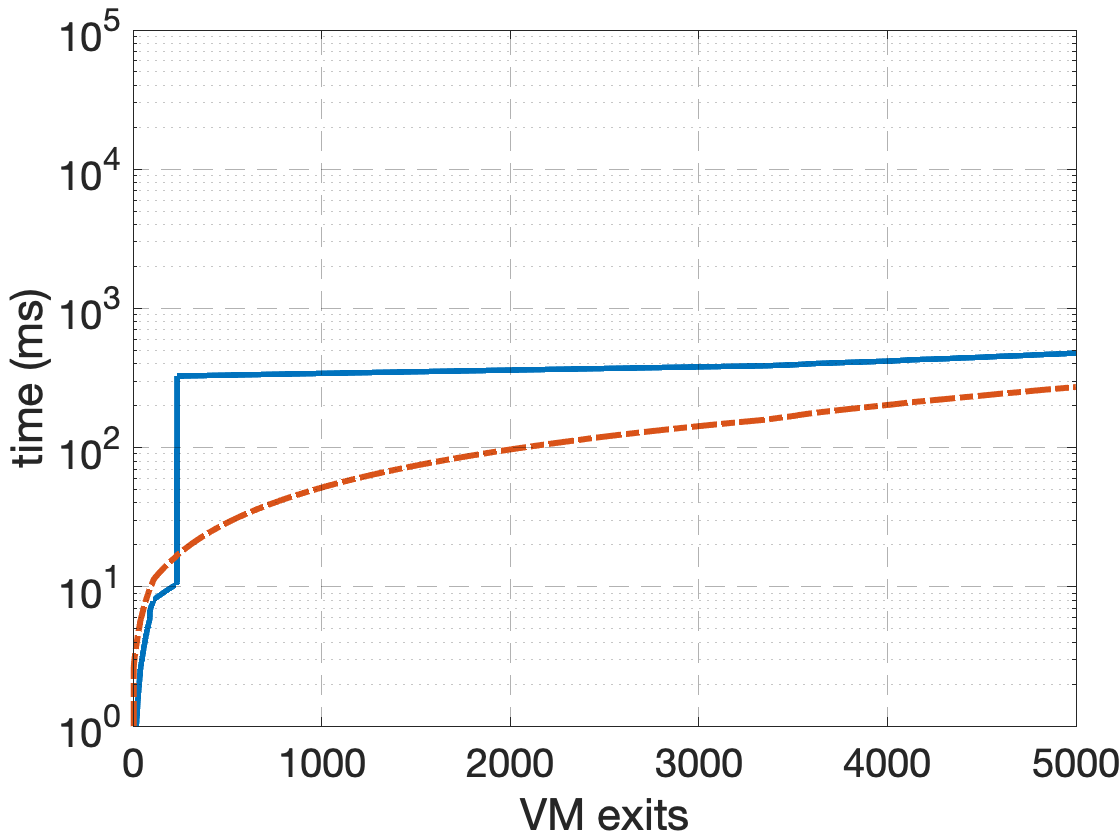

factor=3292000;
%login
load exp_data_efficiency.mat

timestampsmonitoring_d=timestampsrecording.VarName1./factor;
plot(0:4999,timestampsmonitoring_d(1:5000), '-','LineWidth',3);
timestampsmonitoring_d(5000)/1000

ans = 62.6172

hold on;
timestampsmutation_d=timestampsreplaying.VarName1./factor;
plot(0:4999,timestampsmutation_d(1:5000), '-.','LineWidth',3);
timestampsmutation_d(5000)/1000

ans = 0.2230

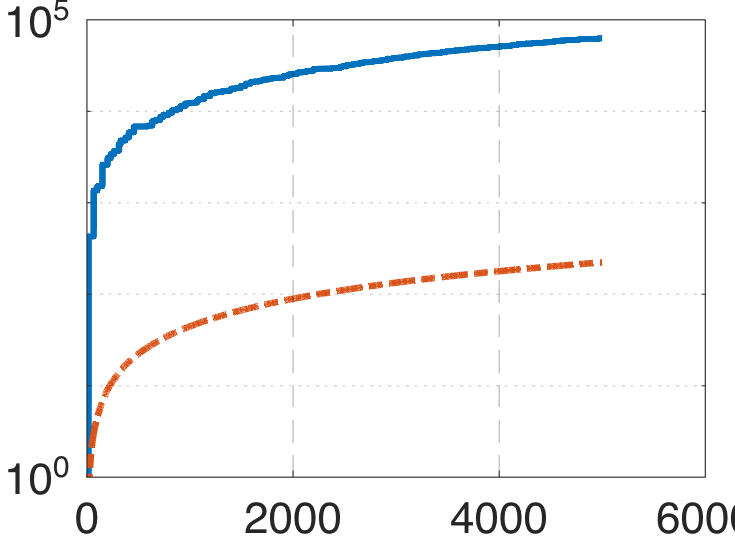

%set(gca, 'YScale', 'log')

set(gca, 'YScale', 'log')
xlabel("VM exits");
ylabel("time (ms)");
%ylabel("CPU cycles");
%xlim([1 4999])
ylim([1 100000])
ax = gca; 
ax.FontSize = 20;
%legend({'recording','replaying'},'Orientation',"horizontal","Location","south")
grid on
ax = gca;
ax.GridColor = [0 0 0];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.3;
ax.Layer = 'top';



%save figure
outerpos = ax.OuterPosition;
ti = ax.TightInset;
left = outerpos(1) + ti(1);
bottom = outerpos(2) + ti(2);
ax_width = outerpos(3) - ti(1) - ti(3);
ax_height = outerpos(4) - ti(2) - ti(4);
ax.Position = [left bottom ax_width ax_height];
a2 = gcf;
a2.PaperPositionMode = 'auto';
fig_pos = a2.PaperPosition;
a2.PaperSize = [fig_pos(3) fig_pos(4)];
print(a2, strcat(fileparts(pwd),'/figures/IDLE_efficiency.pdf'),'-dpdf','-r0');